# Sistemi Dinamici - Prova parziale 01/12/2023

**voto massimo: 4 punti**

Il voto finale sarà costituito dalla somma delle valutazioni conseguite nei due esercizi.

## Esercizio 1

Sono stati acquisiti, con frequenza di campionamento $f_S = 2.5 \;\text{kHz}$, $5000$ campioni di un segnale $y(t)$ costituito da


$$y(t_k) = A\cdot \sin\big(\bar{\omega}_1\,t_k+\delta_1\big) + \epsilon(t_k)  \qquad t_k=k \,T_s\,,\quad k=1,\,2,\,\ldots\,N \;,\quad T_s = \displaystyle \frac{1}{f_s}$$


Del segnale è **noto** il seguente parametro:

- pulsazione $\bar{\omega}_1$ : $\bar{\omega}_1 = 2\,\pi\cdot 50 \; \text{rad/s}$

mentre sono **incogniti** i valori dell'ampiezza $A$ e della fase $\delta_1$.

I campioni acquisiti $y(t_k)$, i corrispondenti istanti di tempo $t_k$ ed i valori dei parametri noti [$\omega_1$ ]sono a disposizione nel MAT file "ESERCIZIO1_DATI.MAT".

### Domanda 1

Si chiede di determinare i valori dei parametri incogniti $A$ e $\delta_1$ utilizzando uno **stimatore ai minimi quadrati**.

#### Suggerimento

L'espressione di $y(t_k)$ può essere riscritta nel modo seguente


$$y(t_k) = \left[A \cos(\delta_1) \right]\cdot \sin\left(\omega_1\,t_k\right) + \left[A \sin \left(\delta_1 \right) \right]\cdot \cos\left(\omega_1\,t_k\right) +\epsilon(t_k)$$


A questo punto, ponendo


$$\vartheta_1 = \left[ A \cos(\delta_1) \right]\;, \qquad \vartheta_2 = \left[ A \sin(\delta_1) \right]$$


si arriva all'espressione


$$y(t) = \varphi^{\top}(t) \cdot \vartheta + \epsilon(t)$$


dove


$$\varphi(t) = \left[ \begin{array}{c} \varphi_1(t) \\ \varphi_2(t) \end{array} \right] \qquad \vartheta =  \left[ \begin{array}{c} \vartheta_1 \\ \vartheta_1 \end{array} \right]$$


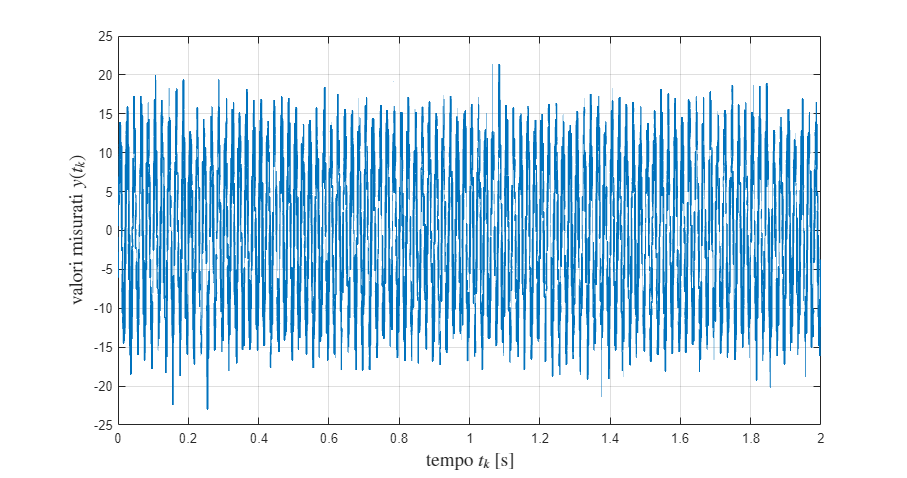

clear
close all
clc

load ESERCIZIO1_DATI.MAT t_k y_t_k

Fs = 2.5e3; % kHz
Ts = 1/Fs;

omega1 = 2*pi*50;


figure('Units','normalized','Position',[0.1, 0.1, 0.8, 0.75]);
plot(t_k, y_t_k, 'LineWidth', 1.5);
grid on;
xlabel('tempo $t_k$ [s]','Interpreter','latex','FontSize',14);
ylabel('valori misurati $y(t_k)$','Interpreter','latex','FontSize',14);

% inserisci il codice che risolve il problema proposto
% usa dei brevi commenti nel codice, per rendere il codice più leggibile


$$y(t_k) = \left[A \cos(\delta_1) \right]\cdot \sin\left(\omega_1\,t_k\right) + \left[A \sin \left(\delta_1 \right) \right]\cdot \cos\left(\omega_1\,t_k\right) +\epsilon(t_k)$$


A questo punto, ponendo


$$\vartheta_1 = \left[ A \cos(\delta_1) \right]\;, \qquad \vartheta_2 = \left[ A \sin(\delta_1) \right]$$


si arriva all'espressione


$$y(t) = \varphi^{\top}(t) \cdot \vartheta + \epsilon(t)$$


dove


$$\varphi(t) = \left[ \begin{array}{c} \varphi_1(t) \\ \varphi_2(t) \end{array} \right] \qquad \vartheta =  \left[ \begin{array}{c} \vartheta_1 \\ \vartheta_1 \end{array} \right]$$


y_t_k = y_t_k';

phi = [
sin(omega1 * t_k);
cos(omega1 * t_k)
    ]';

theta = phi \ y_t_k;

Once we got the values for $Acos(\delta1)$ and $Asin(\delta1)$, we can solve the system of equations and get the two parameters $A$ and $\delta_1$.

We can solve the system of equations as follows:


$$Acos(\delta_1)=theta(1) \rightarrow A = \frac{theta(1)}{cos(\delta_1)}$$



$$Asin(\delta_1)=theta(2) \rightarrow \frac{theta(1)}{cos(\delta_1)}sin(\delta_1) = G \rightarrow tan(\delta_1) = \frac{theta(2)}{theta(1)} \rightarrow \delta_1 = atan(\frac{theta(2)}{theta(1)})$$



$$A = \frac{theta(1)}{cos(\delta_1)}$$


delta_1 = atan(theta(2)/theta(1))

delta_1 = -0.3121

A = theta(1) / cos(delta_1)

A = 12.4569

We can step into calculating the predicted y

y_pred = theta(1) * sin(omega1 * t_k) + theta(2) * cos(omega1 * t_k);

And plotting it against the measured data to check how close our prediction is

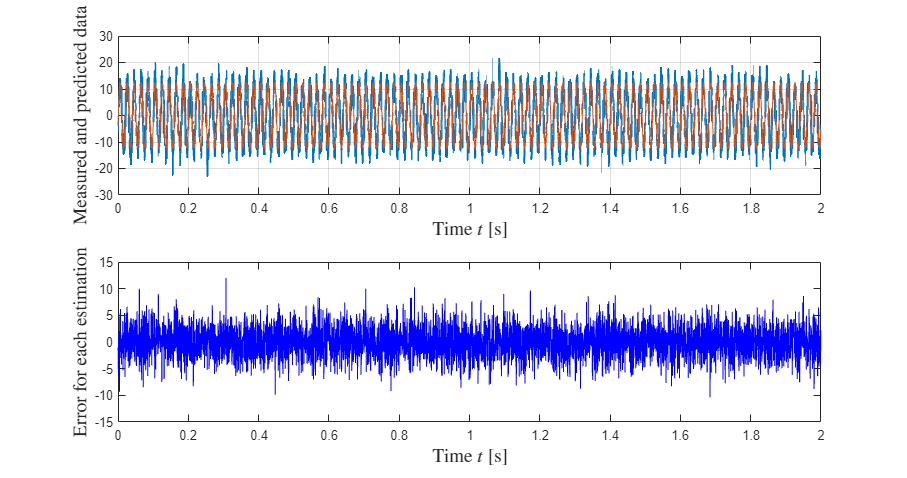

figure('Units','normalized','Position',[0.1, 0.1, 0.8, 0.75]);
subplot(2,1,1)
plot(t_k, y_t_k, 'LineWidth', 1.5);
grid on;
hold on;
plot(t_k, y_pred);
xlabel('Time $t$ [s]','Interpreter','latex','FontSize',14);
ylabel('Measured and predicted data','Interpreter','latex','FontSize',14);

subplot(2,1,2);

grid on; 
errors = y_pred - y_t_k';

[ys, idx]= sort(y_pred);
plot(t_k, errors(idx), '-b');
xlabel('Time $t$ [s]','Interpreter','latex','FontSize',14);
ylabel('Error for each estimation','Interpreter','latex','FontSize',14);

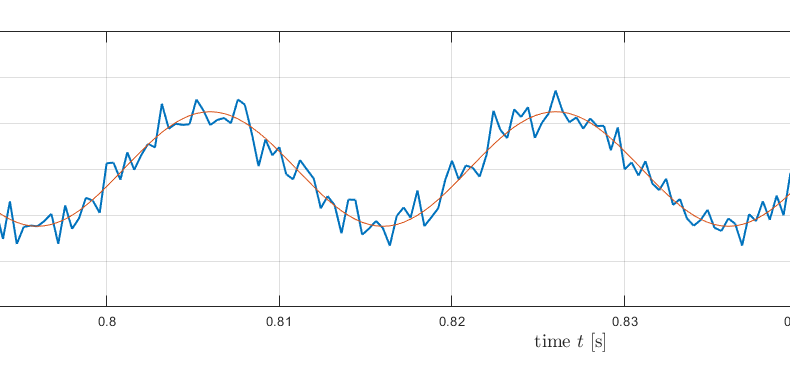

Judging the shape, we can be satisfied with our approximation.

### Domanda 2

Quanto vale la varianza della stima?


$$\text{var}\left[ \hat{\vartheta}_N\right] = \lambda^2_{\epsilon} \cdot \displaystyle \left[\sum_{k=1}^{N} \varphi(t_k) \, \varphi(t_k)^{\top} \right]^{-1}$$


% inserisci il codice che risolve il problema proposto
% usa dei brevi commenti nel codice, per rendere il codice più leggibile

mean(errors)

ans = 0.0439

var(errors)

ans = 8.1169

This last value is the variance of our estimation.

The two results gotten can describe a white noise process, with mean 0 and variance close to 8.